# Ripple sEMG Verification Script

It is important to verify the integrity of the data in order to obtain reproducible results. 

This script load an `.nsx` file (e.g. `.ns2`), and plots the power spectrum profile of the entire session.

Your sEMG power spectrum should look like the image below:

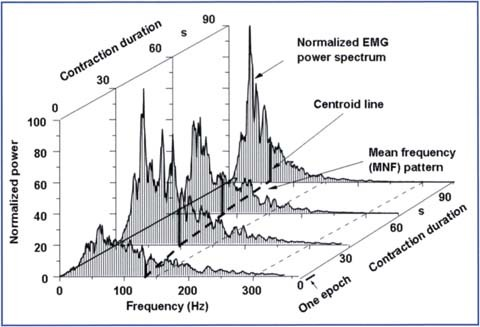

Source: Atlas of Muscle Innervation Zones by Merletti et al. (2012) [https://doi.org/10.1007/978-88-470-2463-2_5](https://doi.org/10.1007/978-88-470-2463-2_5)

## Step 1: Clear the Workspace

clear variables
clear ripple-data-validation
clc

## Step 2: Load Dataset

[header, data] = read_nsx_file('File','D:\AdaptiveEMG_Diagnostics\Virtual Experiments\P20221019\pareticOmnibus0002.ns2');

Loading 0.0 GB of data


## Step 3: Retrieve Metadata

fs = header.Fs;
ch_idx = 15;
ch_signal = data(ch_idx, :);
fprintf("Data from channel %02d sampled at %d kHz.\n%.3f seconds total.", ch_idx, fs, length(ch_signal)/fs);

Data from channel 15 sampled at 1000 kHz.
40.720 seconds total.

## Step 4: Generate Power Spectrum Plot

This code was generated using the MATLAB Signal Analyzer App

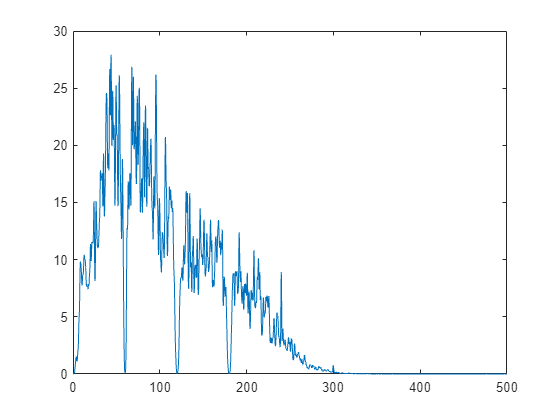

% Parameters
timeLimits = [0 (length(ch_signal)-1)/fs]; % seconds
frequencyLimits = [0 fs/2]; % Hz

% Index into signal time region of interest
ch_signal_ROI = ch_signal(:);
startTime = 0; % seconds
minIdx = ceil( max((timeLimits(1) - startTime) * fs, 0)) + 1;
maxIdx = floor( min((timeLimits(2) - startTime) * fs, length(ch_signal_ROI) -1)) + 1;
ch_signal_ROI = ch_signal_ROI(minIdx:maxIdx);

% Compute spectral estimate
% Run the function call below without output arguments to plot the results
[Pch_signal_ROI, Fch_signal_ROI] = pspectrum(double(ch_signal_ROI),fs, ...
    'FrequencyLimits',frequencyLimits);

plot(Fch_signal_ROI, Pch_signal_ROI)

## Step 5: (Optional) Use the Signal Analyzer to Further Inspect the Data

signalAnalyzer(ch_signal, 'SampleRate', fs)